
format longG
clear;

import keyboard layout

specify the keyboard layout file here

layout = keyboard_importer("C:\Users\taybe\MATLAB Drive\Keyboard_Analysis\keyboard_layouts_en\qwerty.txt", [1, Inf]);
layout_size = size(layout)

layout_size =      3    12


for i = 1:layout_size(2)
    str = layout(:,i);
    if (str == "")
        fprintf('Given layout has empty columns. \nReformatting.')
        layout(:,i) = [];
    end
    [A,B] = size(layout);
    if i == B
        break
    end
end
layout = rmmissing(layout,2,"MinNumMissing",2)

layout = 3×10 string array
    "q"    "w"    "e"    "r"    "t"    "y"    "u"    "i"    "o"    "p"
    "a"    "s"    "d"    "f"    "g"    "h"    "j"    "k"    "l"    ";"
    "z"    "x"    "c"    "v"    "b"    "n"    "m"    ","    "."    "/"


import text for analysis

specify file name here

text = readlines("corpora.txt");

deleting empty lines and making lowercase

TF1 = (text == ""); TF2 = (text=="?"); TF3 = (text=='"');
text(TF1) = []; text(TF2) = "/"; text(TF3) = "'";
text = replace(text,"?","/");
text = replace(text,'"',"'");
text = replace(text,":",";");
text = lower(text);

Make text into one line

text = join(text);
text = join(text,1)

text = "they don't know that we know they know we know. and all you touch and all you see is all your life will ever be. i remember what it was like to love you because i still do. have you ever come to hate the very thing that you helped to create/ you have the power to heal your life, and you need to know that. when you find that once again you long to take your heart back and be free, if you ever find a moment, spare a thought for me. for all the things you've done, for the things you might have done, and for the only thing you have left. don't it make you sad to know that life is more than who you are/ perhaps if you know you are insane then you are not insane. don't it make you sad to know that life is more than who you are/ there is something about yourself that you don't know. there are many things that i would like to say to you but i don't know how. bother me, tell me awful things. you know i love it when you move that on me, love it when you do that on me. you are what you ar

% bigrams
% *Same Finger Bigram (SFB)*: Pressing two keys with the same finger in conjunction. 
% *Disjointed SFB (dSFB)*: Pressing two keys with the same finger, but separated 
% by x letter or a space. *Same Finger Skipgram (SFS)*: Synonym for dSFB. *Lateral 
% Stretch Bigram (LSB)*: A bigram where your hand must stretch laterally, as in 
% using the middle finger following middle column usage on the same hand. An example 
% is |*be*| on QWERTY.
% 
% assign bigrams. For the "qa" bigram for example your have to consider "qa", 
% "q a", "aq", and "a q" 

% this does not consider pionter finger movements

for i = 1:10
    SFB_pat(i*2-1) = (layout(1,i)+layout(2,i))|(layout(2,i)+layout(1,i));
    SFB_pat(i*2) = (layout(3,i)+layout(2,i))|(layout(2,i)+layout(3,i));
end
for i = 1:10
    dSFB_pat(i*2-1) = (layout(1,i)+lettersPattern(1)+layout(2,i))|(layout(1,i)+" "+layout(2,i))...
        |(layout(2,i)+lettersPattern(1)+layout(1,i))|(layout(2,i)+" "+layout(1,i));
    dSFB_pat(i*2) = (layout(3,i)+lettersPattern(1)+layout(2,i))|(layout(3,i)+" "+layout(2,i))...
        |(layout(2,i)+lettersPattern(1)+layout(3,i))|(layout(2,i)+" "+layout(3,i));
end

record bigram types for displaying results

for i = 1:10
    bigram_disp(i*2-1,1) = (layout(1,i)+layout(2,i));
    bigram_disp(i*2,1) = (layout(3,i)+layout(2,i));
end

count bigram occurance

[bigram_1u, bigram_2u] = deal(zeros(20,1));
for i = 1:length(SFB_pat)
    bigram_1u(i,1) = count(text,SFB_pat(i));
    bigram_2u(i,1) = count(text,dSFB_pat(i));
end
SFB = bigram_1u; dSFB = bigram_2u;
table(SFB,dSFB,'RowNames',bigram_disp)

ans = 20×2 table
           SFB     dSFB
          _____    ____

    qa       13     284
    za      346      66
    ws      934    4905
    xs        2     332
    ed    15742    8443
    cd       23    1854
    rf     2647    6624
    vf        1     219
    tg      114    7645
    bg        8     861
    yh      706    3806
    nh      202    9540
    uj     1401     154
    mj        0     196
    ik     3512    2327
    ,k      400     318


bigrams = sortrows(table(SFB,dSFB,'RowNames',bigram_disp),'SFB','descend')

bigrams = 20×2 table
           SFB     dSFB
          _____    ____

    ed    15742    8443
    ol     8210    8668
    ik     3512    2327
    rf     2647    6624
    uj     1401     154
    ws      934    4905
    .l      736    1910
    yh      706    3806
    ,k      400     318
    za      346      66
    nh      202    9540
    tg      114    7645
    p;       27      32
    cd       23    1854
    qa       13     284
    bg        8     861


% find the usage for left and right hand
% left:

for i = 1:5
    left_pat(i*3-2,1) = layout(1,i);
    left_pat(i*3-1,1) = layout(2,i);
    left_pat(i*3,1) = layout(3,i);
end

for i = 1:length(left_pat)
    left_count(i,1) = count(text,left_pat(i));
end
table(left_pat,left_count)

ans = 15×2 table
    left_pat    left_count
    ________    __________

      "q"           1102  
      "a"         114888  
      "z"           1147  
      "w"          35703  
      "s"          90589  
      "x"           1990  
      "e"         183176  
      "d"          55315  
      "c"          34664  
      "r"          82198  
      "f"          30950  
      "v"          16235  
      "t"         138788  
      "g"          31834  
      "b"          23142  


right:

for i = 1:5
    right_pat(i*3-2,1) = layout(1,i+5);
    right_pat(i*3-1,1) = layout(2,i+5);
    right_pat(i*3,1) = layout(3,i+5);
end
for i = 1:length(right_pat)
    right_count(i,1) = count(text,right_pat(i));
end
table(right_pat,right_count)

ans = 15×2 table
    right_pat    right_count
    _________    ___________

       "y"          39332   
       "h"          80517   
       "n"         104079   
       "u"          47825   
       "j"           2361   
       "m"          39345   
       "i"         105620   
       "k"          14709   
       ","          21630   
       "o"         121774   
       "l"          62850   
       "."          24484   
       "p"          24237   
       ";"           1559   
       "/"           2107   


letter = ((cat(1,left_pat,right_pat)));
character_sum = sum(cat(1,left_count,right_count))

character_sum =      1534150


percent = cat(1,left_count,right_count)/character_sum;
key_usage = sortrows(table(letter,percent),'percent','descend')

key_usage = 30×2 table
    letter         percent      
    ______    __________________

     "e"       0.119399015741616
     "t"      0.0904657302089105
     "o"      0.0793755499788156
     "a"      0.0748870710165238
     "i"      0.0688459407489489
     "n"      0.0678414757357494
     "s"      0.0590483329531011
     "r"        0.05357885474041
     "h"      0.0524831339829873
     "l"      0.0409673108887658
     "d"       0.036055796369325
     "u"      0.0311736140533846
     "m"      0.0256461232604374
     "y"      0.0256376495127595
     "w"      0.0232721702571457
     "c"      0.0225949222696607


LSB: lateral stretch bigrams, that would be the bigrams where the fingers stretch to the middle columns

table(letter,percent)

ans = 30×2 table
    letter          percent      
    ______    ___________________

     "q"      0.00071831307238536
     "a"       0.0748870710165238
     "z"      0.00074764527588567
     "w"       0.0232721702571457
     "s"       0.0590483329531011
     "x"      0.00129713522145814
     "e"        0.119399015741616
     "d"        0.036055796369325
     "c"       0.0225949222696607
     "r"         0.05357885474041
     "f"       0.0201740377407685
     "v"       0.0105824071961673
     "t"       0.0904657302089105
     "g"       0.0207502525828635
     "b"       0.0150845745200926
     "y"       0.0256376495127595


middle_letter = letter(13:18); middle_percent = percent(13:18); 
lateral_move = table(middle_letter,middle_percent,'RowNames',middle_letter)

lateral_move = 6×2 table
         middle_letter      middle_percent  
         _____________    __________________

    t         "t"         0.0904657302089105
    g         "g"         0.0207502525828635
    b         "b"         0.0150845745200926
    y         "y"         0.0256376495127595
    h         "h"         0.0524831339829873
    n         "n"         0.0678414757357494


for i = 1:3
    lateral_SFB_pat(i) = (layout(i,4)+layout(i,5))|(layout(i,5)+layout(i,4));
end
for i = 1:3
    lateral_SFB_pat(i+3) = (layout(i,6)+layout(2,7))|(layout(i,7)+layout(i,6));
end
for i = 1:3
    lateral_SFB_disp(i,1) = (layout(i,4)+layout(i,5));
    lateral_dSFB_disp(i,1) = (layout(i,4)+layout(i,5));
end
for i = 1:3
    lateral_SFB_disp(i+3,1) = (layout(i,6)+layout(i,7));
    lateral_dSFB_disp(i+3,1) = (layout(i,6)+layout(2,7));
end
for i = 1:3
    lateral_dSFB_pat(i) = (layout(i,4)+lettersPattern(1)+layout(i,5))|(layout(i,4)+" "+layout(i,5))...
        |(layout(i,5)+lettersPattern(1)+layout(i,4))|(layout(i,5)+" "+layout(i,4));
end
for i = 1:3
    lateral_dSFB_pat(i+3) = (layout(i,6)+lettersPattern(1)+layout(i,7))|(layout(i,6)+" "+layout(i,7))...
        |(layout(i,7)+lettersPattern(1)+layout(i,6))|(layout(i,7)+" "+layout(i,6));
end
for i = 1:length(lateral_SFB_pat)
    diag_1u_SFB_count(i,1) = count(text,lateral_SFB_pat(i));
end
for i = 1:length(lateral_dSFB_pat)
    diag_1u_dSFB_count(i,1) = count(text,lateral_dSFB_pat(i));
end
table(lateral_SFB_disp,diag_1u_SFB_count,lateral_dSFB_disp,diag_1u_dSFB_count)

ans = 6×4 table
    lateral_SFB_disp    diag_1u_SFB_count    lateral_dSFB_disp    diag_1u_dSFB_count
    ________________    _________________    _________________    __________________

          "rt"                6986                 "rt"                 12563       
          "fg"                  19                 "fg"                   923       
          "vb"                  30                 "vb"                    96       
          "yu"                 223                 "yj"                 11850       
          "hj"                   0                 "hj"                    64       
          "nm"                 219                 "nj"                  6858       


lateral_SFB_percent = diag_1u_SFB_count/(2*character_sum);
lateral_dSFB_percent = diag_1u_dSFB_count/(2*character_sum);
lateral_bigram = table(middle_letter,middle_percent,'RowNames',middle_letter)

lateral_bigram = 6×2 table
         middle_letter      middle_percent  
         _____________    __________________

    t         "t"         0.0904657302089105
    g         "g"         0.0207502525828635
    b         "b"         0.0150845745200926
    y         "y"         0.0256376495127595
    h         "h"         0.0524831339829873
    n         "n"         0.0678414757357494


lateral_SFB = sortrows(table(lateral_SFB_disp,lateral_SFB_percent,lateral_dSFB_percent),'lateral_SFB_percent','descend')

lateral_SFB = 6×3 table
    lateral_SFB_disp    lateral_SFB_percent     lateral_dSFB_percent
    ________________    ____________________    ____________________

          "rt"           0.00227683081836848       0.004094449695271
          "yu"          7.26786820063227e-05      0.0038620734608741
          "nm"          7.13750285174201e-05     0.00223511390672359
          "vb"          9.77740116676987e-06    3.12876837336636e-05
          "fg"          6.19235407228759e-06    0.000300818042564286
          "hj"                             0    2.08584558224424e-05


2u bigram

for i = 1:10
    SFB_2u_disp(i,1) = layout(1,i)+layout(3,i);
    SFB_2u_pat(i,1) = layout(1,i)+layout(3,i)|layout(3,i)+layout(1,i);
    dSFB_2u_pat(i,1) = layout(1,i)+" "+layout(3,i)|layout(3,i)+lettersPattern(1)+layout(1,i)|layout(1,i)+lettersPattern(1)+layout(3,i)|layout(3,i)+" "+layout(1,i);
end
for i = 1:length(dSFB_2u_pat)
    SFB_2u(i,1) = count(text,dSFB_2u_pat(i));
    dSFB_2u(i,1) = count(text,dSFB_2u_pat(i));
end
table(SFB_2u_disp, SFB_2u,dSFB_2u)

ans = 10×3 table
    SFB_2u_disp    SFB_2u    dSFB_2u
    ___________    ______    _______

       "qz"            0         0  
       "wx"           13        13  
       "ec"         7343      7343  
       "rv"         5372      5372  
       "tb"         5031      5031  
       "yn"         3810      3810  
       "um"          935       935  
       "i,"         3789      3789  
       "o."         2946      2946  
       "p/"           39        39  


diagonal 1u and 2u

for i = 1:2
    diag_1u_disp(2*i-1,1) = layout(i,4)+layout(i+1,5);
    diag_1u_disp(2*i,1) = layout(i+1,4)+layout(i,5);
end
for i = 1:2
    diag_1u_disp(2*i-1+4,1) = layout(i,6)+layout(i+1,7);
    diag_1u_disp(2*i+4,1) = layout(i+1,6)+layout(i,7);
end
for i = 1:2
    diag_1u_SFB_pat(2*i-1,1) = layout(i,4)+layout(i+1,5)|layout(i+1,5)+layout(i,4);
    diag_1u_SFB_pat(2*i,1) = layout(i+1,4)+layout(i,5)|layout(i,5)+layout(i+1,4);
end
for i = 1:2
    diag_1u_SFB_pat(2*i-1+4,1) = layout(i,6)+layout(i+1,7)|layout(i+1,7)+layout(i,6);
    diag_1u_SFB_pat(2*i+4,1) = layout(i+1,6)+layout(i,7)|layout(i,7)+layout(i+1,6);
end
for i = 1:2
    diag_1u_dSFB_pat(2*i-1) = layout(i,4)+lettersPattern(1)+layout(i+1,5)|layout(i+1,5)+lettersPattern(1)+layout(i,4)|...
        layout(i,4)+" "+layout(i+1,5)|layout(i+1,5)+" "+layout(i,4);

    diag_1u_dSFB_pat(2*i) = layout(i+1,4)+lettersPattern(1)+layout(i,5)|layout(i,5)+lettersPattern(1)+layout(i+1,4)|...
        layout(i+1,4)+" "+layout(i,5)|layout(i,5)+" "+layout(i+1,4);
end
for i = 1:2
    diag_1u_dSFB_pat(2*i-1+4) = layout(i,6)+lettersPattern(1)+layout(i+1,7)|layout(i+1,7)+lettersPattern(1)+layout(i,6)|...
        layout(i,6)+" "+layout(i+1,7)|layout(i+1,6)+" "+layout(i,7);
    diag_1u_dSFB_pat(2*i+4) = layout(i+1,6)+lettersPattern(1)+layout(i,7)|layout(i,7)+lettersPattern(1)+layout(i+1,6)|...
        layout(i+1,6)+" "+layout(i,7)|layout(i,7)+" "+layout(i+1,6);
end
for i = 1:length(diag_1u_SFB_pat)
    diag_1u_SFB_count(i,1) = count(text,diag_1u_SFB_pat(i));
end
for i = 1:length(diag_1u_dSFB_pat)
    diag_1u_dSFB_count(i,1) = count(text,diag_1u_dSFB_pat(i));
end
table(diag_1u_disp,diag_1u_SFB_count,diag_1u_dSFB_count)

ans = 8×3 table
    diag_1u_disp    diag_1u_SFB_count    diag_1u_dSFB_count
    ____________    _________________    __________________

        "rg"              2349                  2672       
        "ft"               947                  4686       
        "fb"                 6                   661       
        "vg"                 0                   690       
        "yj"                 1                   248       
        "hu"               921                  4541       
        "hm"                78                  3154       
        "nj"               132                   149       


diag_SFB_percent = diag_1u_SFB_count/(2*character_sum);
diag_dSFB_percent = diag_1u_dSFB_count/(2*character_sum);
lateral_SFB = sortrows(table(diag_1u_disp,diag_SFB_percent,diag_dSFB_percent),'diag_SFB_percent','descend')

lateral_SFB = 8×3 table
    diag_1u_disp      diag_SFB_percent       diag_dSFB_percent  
    ____________    ____________________    ____________________

        "rg"        0.000765570511358081     0.00087084053058697
        "ft"        0.000308639963497702     0.00152723006224945
        "hu"        0.000300166215819835     0.00147997262327673
        "nj"        4.30205651337874e-05    4.85610924616237e-05
        "hm"        2.54212430336017e-05     0.00102793077599974
        "fb"        1.95548023335397e-06    0.000215428739041163
        "yj"        3.25913372225662e-07    8.08265163119643e-05
        "vg"                           0    0.000224880226835707


% 2u diagonal
diag_2u_disp(1,1) = layout(1,4)+layout(3,5);
diag_2u_disp(2,1) = layout(3,4)+layout(1,5);
diag_2u_disp(3,1) = layout(1,6)+layout(3,7);
diag_2u_disp(4,1) = layout(3,6)+layout(1,7);
for i = 1:2
    diag_2u_SFB_pat(i,1) = layout(1,6-i)+layout(3,i+3)|layout(3,i+3)+layout(1,6-i);
end

for i = 1:2
    diag_2u_SFB_pat(i+2,1) = layout(1,8-i)+layout(3,i+5)|layout(3,i+5)+layout(1,8-i);
end

for i = 1:2
    diag_2u_dSFB_pat(i,1) = layout(1,6-i)+" "+layout(3,i+3)|layout(3,i+3)+lettersPattern(1)+layout(1,6-i)|layout(1,6-i)+lettersPattern(1)+layout(3,i+3)|layout(3,i+3)+" "+layout(1,6-i);
end

for i = 1:2
    diag_2u_dSFB_pat(i+2,1) = layout(1,8-i)+lettersPattern(1)+layout(3,i+5)|layout(3,i+5)+" "+layout(1,8-i)|layout(1,8-i)+" "+layout(3,i+5)|layout(3,i+5)+lettersPattern(1)+layout(1,8-i);
end
for i = 1:length(diag_2u_SFB_pat)
    diag_2u_SFB_count(i,1) = count(text,diag_2u_SFB_pat(i));
end
for i = 1:length(diag_2u_dSFB_pat)
    diag_2u_dSFB_count(i,1) = count(text,diag_2u_dSFB_pat(i));
end
table(diag_2u_disp,diag_2u_SFB_count,diag_2u_dSFB_count)

ans = 4×3 table
    diag_2u_disp    diag_2u_SFB_count    diag_2u_dSFB_count
    ____________    _________________    __________________

        "rb"                29                   865       
        "vt"              1536                  2867       
        "ym"              5049                  2411       
        "nu"              3028                  1477       


finding the character count usage

a = reshape(left_count,[3,5]); b = reshape(right_count,[3,5]); c = cat(2,a,b);
key_freq = c/sum(c,'all')

key_freq =        0.00071831307238536        0.0232721702571457         0.119399015741616          0.05357885474041        0.0904657302089105        0.0256376495127595        0.0311736140533846        0.0688459407489489        0.0793755499788156        0.0157983248052668
        0.0748870710165238        0.0590483329531011         0.036055796369325        0.0201740377407685        0.0207502525828635        0.0524831339829873       0.00153896294364958       0.00958771958413454        0.0409673108887658       0.00101619789459962
       0.00074764527588567       0.00129713522145814        0.0225949222696607        0.0105824071961673        0.0150845745200926        0.0678414757357494        0.0256461232604374        0.0140990124824822        0.0159593260111462       0.00137339895055894


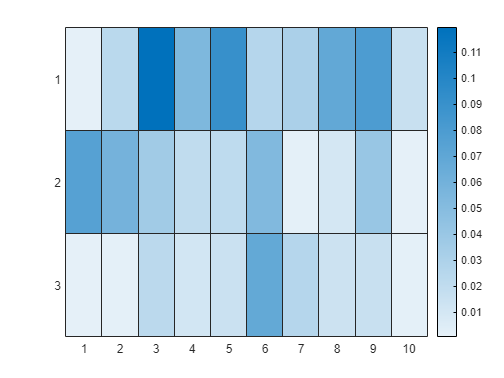

figure()
h = heatmap(key_freq);

Left and right hand usage

left_hand_usage = sum(key_freq(:,1:5),'all')

left_hand_usage =          0.548656259166314


right_hand_usage = 1-left_hand_usage

right_hand_usage =          0.451343740833686


finger usage. 1 is left pinky and 8 is right pinky

finger_freqs = sum(key_freq);
% shared columns in the middle of the keyboard
finger_4 = sum(finger_freqs(4:5));
finger_5 = sum(finger_freqs(6:7));
finger_8 = sum(finger_freqs(10:end));
data = key_freq;
finger_freqs = cat(2,finger_freqs(1:3),finger_4,finger_5,finger_freqs(8:9),finger_8)

finger_freqs =         0.0763530293647948        0.0836176384317048         0.178049734380602         0.210635856989212         0.204320959488968        0.0925326728155656         0.136302186878728        0.0181879216504253
